% This code is to play with one signal at a time, see the error and firing
% rate using the conventional IF-TEM method

load('chirp_signal.mat', 'fd', 'td');

Fm = 100;
BW = 2 * pi * Fm;
c = 1;
td = td(:).';
[time_stamps, loc, f_k_hat, f_sampled, b, tn] = conventional_iftem_sampling_chirp(fd, td, Fm, BW,c);

Energy of the signal: 0.14538
Epsilon value: 1956.1008
Perfect reconstruction NOT guaranteed


NoF=length(time_stamps)-1

NoF = 795

%save('time_conv.mat', 'time_stamps')
%save('tn_conv.mat','tn')

Td = 1e-6;
for n = 1:NoF - 1
        
        sn(n) = (tn(n+1) + tn(n)) / 2;
        sn(n) = floor(sn(n) / Td) * Td;

        
end


## Reconstruction

iter=7;
[F_est,sn1] = signal_reconstruction_CIFTEM(NoF, td, f_k_hat, time_stamps, loc, tn, BW, Fm, iter);
%10 * log10( norm(fd(30000:end-30000) - F_est(30000:end-30000,iter))^2 / norm(fd(30000:end-30000)).^2 )
10 * log10( norm(fd(50000:end-50000) - F_est(50000:end-50000,iter))^2 / norm(fd(50000:end-50000)).^2 )

ans = -59.6356

disp(['Length of td: ', num2str(length(td))]);

Length of td: 900001


disp(['Length of fd: ', num2str(length(fd))]);

Length of fd: 900001


disp(['Size of F_est: ', mat2str(size(F_est))]);

Size of F_est: [900001 7]


disp(['iter: ', num2str(iter)]);

iter: 7


disp(['samples: ', num2str(length(time_stamps)-1)]);

samples: 795


%10 * log10( norm(fd(30000:end-30000) - F_est(30000:end-30000,iter))^2 / norm(fd(30000:end-30000)).^2 )
10 * log10( norm(fd(50000:end-50000) - F_est(50000:end-50000,iter))^2 / norm(fd(50000:end-50000)).^2 )

ans = -59.6356

disp(['Length of td: ', num2str(length(td))]);

Length of td: 900001


disp(['Length of fd: ', num2str(length(fd))]);

Length of fd: 900001


disp(['Size of F_est: ', mat2str(size(F_est))]);

Size of F_est: [900001 7]


disp(['iter: ', num2str(iter)]);

iter: 7


c1 = 1; c = c1;
% === Normalize the signal ===
normalized_fd = (fd ) / c;

% === Compute firing rate (density) as inverse of inter-spike intervals ===
firing_density = 1 ./ time_stamps;                % Instantaneous firing rate
firing_time = (tn(1:end-1) + tn(2:end)) / 2;  % Midpoints for firing

% === Compute derivative and related quantities ===
signal_derivative = gradient(normalized_fd, td);        
mod_signal_derivative = abs(signal_derivative);         
product_term = normalized_fd .* mod_signal_derivative;  

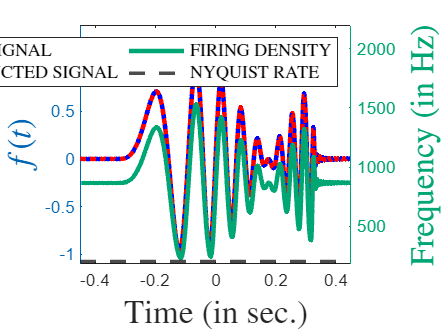


%% === Plot 1: Normalized Signal and Firing Density ===
figure;

% --- Left y-axis: Signal ---
yyaxis left
plot(td, normalized_fd, 'b', 'LineWidth', 2.5, 'DisplayName', 'ORIGINAL SIGNAL'); hold on;
plot(td, F_est(:,iter)/c1, 'r:', 'DisplayName', 'RECONSTRUCTED SIGNAL', 'LineWidth', 2.5); 
ylabel('$f(t)$', 'Interpreter', 'latex', 'FontSize', 18);

% Set left axis color to blue
ax = gca;
ax.YAxis(1).Color = [0 0.4 0.7];   % Blue

% --- Right y-axis: Firing Density ---
yyaxis right
plot(firing_time(2:end), firing_density(2:end-1), 'Color','[0 0.65 0.45]', 'LineWidth', 2.5, ...
    'DisplayName', 'FIRING DENSITY');
yline(200, 'k--', 'LineWidth', 2, 'DisplayName', 'NYQUIST RATE');
ylabel('Frequency (in Hz)', 'Interpreter', 'latex', 'FontSize', 18);

% Set right axis color to magenta
ax.YAxis(2).Color = [0 0.65 0.45];   % Magenta

% --- Common axes formatting ---
yyaxis right
ylim([180, 2200]);
yyaxis left
ylim([-1.1, 1.4]);

% --- Legend ---
legend('show', 'Interpreter', 'latex', 'FontSize', 10, 'Location', 'northeast', 'NumColumns', 2);

xlabel('Time (in sec.)', 'Interpreter', 'latex', 'FontSize', 18);
xlim([-0.45, 0.45]);

%set(gca, 'LooseInset', max(get(gca, 'TightInset'), 0.02))

% exportgraphics(gcf, 'new_compact_conventional.pdf', ...
%     'ContentType', 'vector', ...
%     'BackgroundColor', 'none', ...
%     'Resolution', 300);
